# Plot ERP Central line

pathStat variable is where all the GND are stored. 

pathStat =  'D:\Kevin_Cepeda\Matlab\NewMatLabData\Neuroengineering\SB_2021\Historials\GND3Data_Mark\';

## (1) Load GND & get bin difference

load([pathStat , 'GNDTheta.GND'],'-mat');
GNDTheta=bin_dif(GND,2,1,'X/O Task Target-Standards');

<<New bin successfully created>>
Condition Code 1: Experiment (not cal pulses)
Bin 3: X/O Task Target-Standards


load([pathStat , 'GNDBeta.GND'],'-mat');
GNDBeta=bin_dif(GND,2,1,'X/O Task Target-Standards');

<<New bin successfully created>>
Condition Code 1: Experiment (not cal pulses)
Bin 3: X/O Task Target-Standards


## (2) Calculate Permutation test

GNDTheta = tmaxGND(GNDTheta,3,'time_wind',[100 600],'save_GND','no',...
    'plot_mn_topo','no','plot_raster','no','plot_gui','no','output_file', 'Thetatxt.csv');

Experiment: An Experiment
22 out of 22 participants have data in relevant bin.
Time Window #1:
Attempting to use time boundaries of 100 to 600 ms for hypothesis test.
Exact window boundaries are 100 to 600 ms (that's from time point 76 to 201).
Testing null hypothesis that the grand average ERPs in Bin 3 (X/O Task Target-Standards) have a mean of 0.000000 microvolts.
Alternative hypothesis is that the ERPs differ from 0.000000 (i.e., two-tailed test).
mxt_perm1: Number of channels: 22
mxt_perm1: Number of time points: 126
mxt_perm1: Total # of comparisons: 2772
mxt_perm1: Number of participants: 22
t-score degrees of freedom: 21
Executing permutation test with 2500 permutations...
Permutations completed: 100, 200, 300, 400, 500, 600, 700, 800, 900, 1000
1100, 1200, 1300, 1400, 1500, 1600, 1700, 1800, 1900, 2000
2100, 2200, 2300, 2400, 2500
Desired family-wise alpha level: 0.050000
Estimated actual family-wise alpha level: 0.050000
Critical t-score(s):-4.5611      4.5611
That correspond

GNDBeta = tmaxGND(GNDBeta,3,'time_wind',[100 600],'save_GND','no',...
    'plot_mn_topo','no','plot_raster','no','plot_gui','no');

Experiment: An Experiment
23 out of 23 participants have data in relevant bin.
Time Window #1:
Attempting to use time boundaries of 100 to 600 ms for hypothesis test.
Exact window boundaries are 100 to 600 ms (that's from time point 76 to 201).
Testing null hypothesis that the grand average ERPs in Bin 3 (X/O Task Target-Standards) have a mean of 0.000000 microvolts.
Alternative hypothesis is that the ERPs differ from 0.000000 (i.e., two-tailed test).
mxt_perm1: Number of channels: 22
mxt_perm1: Number of time points: 126
mxt_perm1: Total # of comparisons: 2772
mxt_perm1: Number of participants: 23
t-score degrees of freedom: 22
Executing permutation test with 2500 permutations...
Permutations completed: 100, 200, 300, 400, 500, 600, 700, 800, 900, 1000
1100, 1200, 1300, 1400, 1500, 1600, 1700, 1800, 1900, 2000
2100, 2200, 2300, 2400, 2500
Desired family-wise alpha level: 0.050000
Estimated actual family-wise alpha level: 0.050000
Critical t-score(s):-4.6079      4.6079
That correspond

## (3) Get Ptest Vector

This calculation is only for theta_if - theta_f and beta_if - beta_f. 

Correcting for multiple comparisons via permutation test.
Estimated alpha level of critical t-scores: 0.050000.


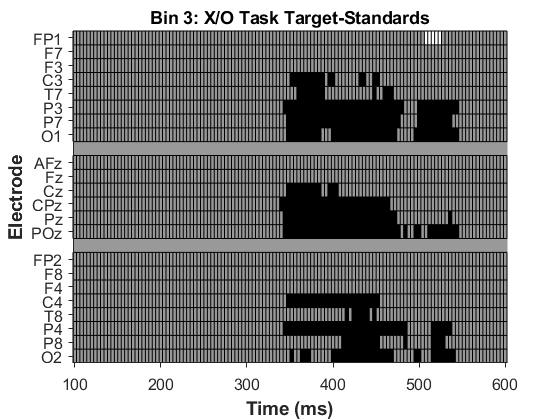

Theta_Ptest =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

Theta_Ptest = sig_raster(GNDTheta,1);

Theta_Ptest([9,16],:) = [];

Theta_Ptest =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     

Correcting for multiple comparisons via permutation test.
Estimated alpha level of critical t-scores: 0.050000.


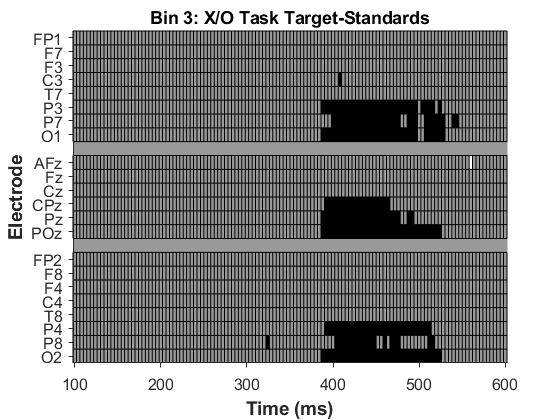

Theta_Ptest = Theta_Ptest([9,10,11,12,13,14],:);
Theta_Ptest(Theta_Ptest == 0) = nan;
Theta_Ptest(Theta_Ptest == 1) = -1;
Beta_Ptest = sig_raster(GNDBeta,1);

Beta_Ptest([9,16],:) = [];
Beta_Ptest = Beta_Ptest([9,10,11,12,13,14],:);
Beta_Ptest(Beta_Ptest == 0) = nan;

## (4) Plot ERPs

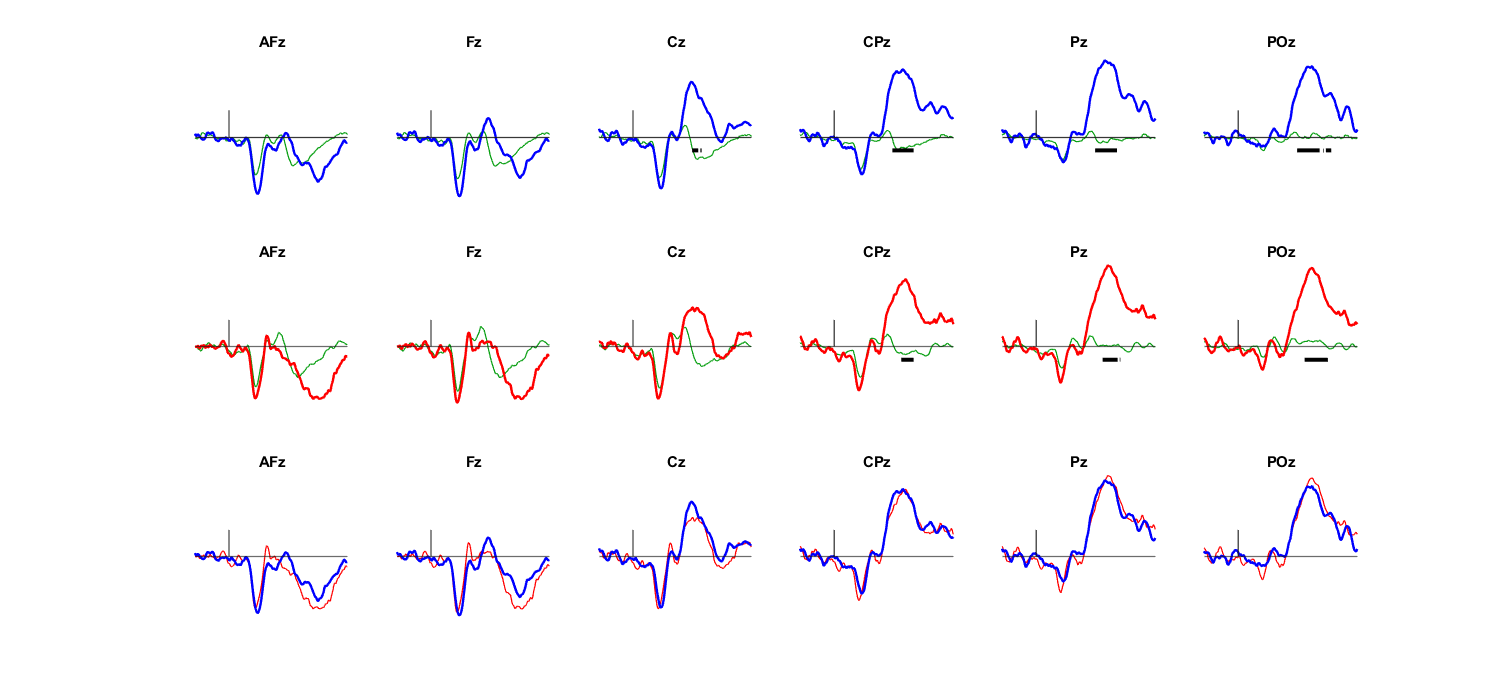

ptestTimes =  linspace(100,600,126);

ColorList = {[10/255 160/255 20/255],[0 0 1],[1 0 0]};
plotERP_central(ThetaStruct.Fstim,ColorList(1),1,0.9)
plotERP_central(ThetaStruct.IFstim,ColorList(2),1,1.8)

for i = 1:6
    subplot(3,6,i)
    plot(ptestTimes,Theta_Ptest(i,:), 'Color', [0 0 0], 'LineWidth', 3) 
end

plotERP_central(BetaStruct.Fstim,ColorList(1),2,0.9)
plotERP_central(BetaStruct.IFstim,ColorList(3),2,1.8)

for i = 1:6
    subplot(3,6,6+i)
    plot(ptestTimes,Beta_Ptest(i,:), 'Color', [0 0 0], 'LineWidth', 3) 
end

plotERP_central(BetaStruct.IFstim,ColorList(3),3,0.9)
plotERP_central(ThetaStruct.IFstim,ColorList(2),3,1.8)
%saveas(gcf,"fullGA_Mark" + ".pdf");